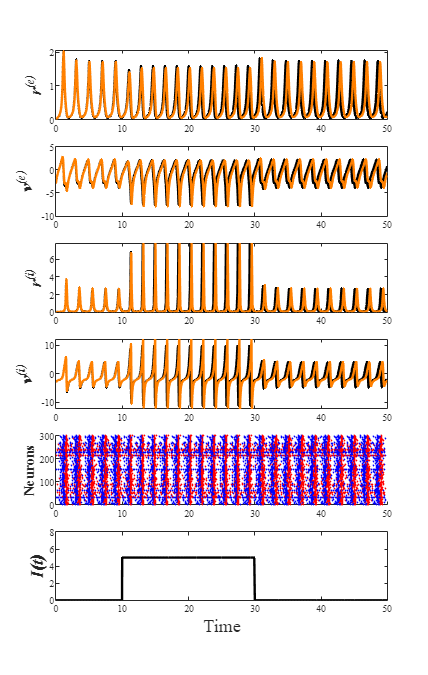

% Load the data
load('FRe_CUBA2.mat');
load('FRre_CUBA2.mat');
load('Ve_CUBA2.mat');
load('Vre_CUBA2.mat');
load('FRi_CUBA2.mat');
load('FRri_CUBA2.mat');
load('Vi_CUBA2.mat');
load('Vri_CUBA2.mat');
load('Rastere_CUBA2.mat');
load('Rasteri_CUBA2.mat');

% Set default properties for the current script
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

ti = 0;
dt = 0.001;
tf = 50;
fs = 1/dt;
tvec = ti+dt:dt:tf;

% Apply moving average
FRe_matlab = movmean(FRe_matlab, 30);
Ve_matlab = movmean(Ve_matlab, 100);
FRi_matlab = movmean(FRi_matlab, 30);
Vi_matlab = movmean(Vi_matlab, 100);

% Create the subplot
figure('Units', 'inches', 'Position', [0, 0, 7, 24]);

% Subplot 1: Firing rates exc
subplot(6, 1, 1);
plot(tvec, FRe_matlab, 'color', 'black', 'LineWidth', 2);
hold on;
plot(tvec, FRre_matlab, 'color', [1, 0.5, 0], 'LineWidth', 2);
ylabel('r^{(e)}', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold');
hold off;

% Subplot 2: Voltage exc
subplot(6, 1, 2);
plot(tvec, Ve_matlab, 'color', 'black', 'LineWidth', 2);
hold on;
plot(tvec, Vre_matlab, 'color', [1, 0.5, 0], 'LineWidth', 2);
ylabel('v^{(e)}', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold');
hold off;

% Subplot 3: Firing rates inh
subplot(6, 1, 3);
plot(tvec, FRi_matlab, 'color', 'black', 'LineWidth', 2);
hold on;
plot(tvec, FRri_matlab, 'color', [1, 0.5, 0], 'LineWidth', 2);
ylabel('r^{(i)}', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold');
hold off;

% Subplot 4: Voltage inh
subplot(6, 1, 4);
plot(tvec, Vi_matlab, 'color', 'black', 'LineWidth', 2);
hold on;
plot(tvec, Vri_matlab, 'color', [1, 0.5, 0], 'LineWidth', 2);
ylabel('v^{(i)}', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold');
hold off;

% Subplot 5: Raster plot
subplot(6, 1, 5);

% Plot excitatory neurons with blue points
hold on;
for neuron = 1:size(Rastere_matlab, 1)
    for time = 1:size(Rastere_matlab, 2)
        if Rastere_matlab(neuron, time) == 0
            plot(tvec(time), neuron,'bo', 'MarkerSize', 1, 'MarkerFaceColor', 'b'); % Blue points for excitatory neurons
        end
        if Rasteri_matlab(neuron, time) == -1
            plot(tvec(time), neuron,'ro', 'MarkerSize', 1, 'MarkerFaceColor', 'r'); % Red points for inhibitory neurons
        end
    end
end

hold off;

% Label the axes
ylabel('Neurons', 'FontSize', 12, 'FontWeight', 'bold');

% Subplot 6: Applied current
subplot(6, 1, 6);
Pulse = zeros(1, length(tvec));
Pulse(10/0.001:30/0.001) = 5;
plot(tvec, Pulse, 'color', 'black', 'LineWidth', 2);
xlabel('Time', 'FontSize', 15);
ylabel('I(t)', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold');
ylim([0, 8]);

% Save the figure in high quality
print('HighQualityFigure', '-dpng', '-r300');